# KOLO

clear
close all
syms s_s
syms w_s
assume(w_s, 'positive')
assume(w_s, 'real')
s_t = tf('s');

%%INPUTS________________________________

%A = [0, 0; 0, 0]; B = [0, 0; 0, 0]; C = [0, 0; 0, 0]; D = [0, 0; 0, 0]
%G_L = ss(A, B, C, D)
%[num, denom] = ss2tf(A, B, C, D)
%G_L = tf(num, demon)

G_L = -1 * tf([0, 4], [3 1]) * tf([-5 1], [2 1])

G_L =
 
     20 s - 4
  ---------------
  6 s^2 + 5 s + 1
 
Continuous-time transfer function.



[A, B, C, D] = tf2ss(G_L.Numerator{1, 1}, G_L.Denominator{1, 1})

A =    -0.8333   -0.1667
    1.0000         0


B =      1
     0


C =     3.3333   -0.6667


D = 0


%KOLO_______________________________
m1 = -0.24;
m2 = 0.21;
m0 = 0.1;

%%___________________________________________________________

G_s = poly2sym(G_L.Numerator{1, 1}, s_s) / poly2sym(G_L.Denominator{1, 1}, s_s)

$$G\_s = \frac{20\,s_{s}-4}{6\,{s_{s}}^{2}+5\,s_{s}+1}$$

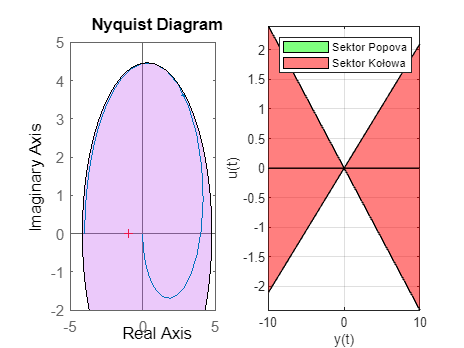


m1m2plot(m1, m2, G_L, 0)


Abm0c = A + m0.*B*C

Abm0c =    -0.5000   -0.2333
    1.0000         0


eig(Abm0c)

ans =   -0.2500 + 0.4133i
  -0.2500 - 0.4133i



y = -10:0.1:10;

# SYMS

syms a_s b_s c_s
assume(a_s, 'real')
assume(b_s, 'real')
assume(c_s, 'real')
syms s_s
A = [[0 a_s]; [1 0]]; B = [b_s; 0]; C = [3 c_s];

Abm0c = A + m0.*B*C;
simplify(eig(Abm0c))

$$ans = \left(\begin{array}{c} \frac{3\,b_{s}}{20}-\frac{\sqrt{9\,{b_{s}}^{2}+40\,c_{s}\,b_{s}+400\,a_{s}}}{20}\\ \frac{3\,b_{s}}{20}+\frac{\sqrt{9\,{b_{s}}^{2}+40\,c_{s}\,b_{s}+400\,a_{s}}}{20} \end{array}\right)$$


G_s_par = (a_s*s_s - 1)/(b_s*s_s^2 + 5*s_s - c_s)

$$G\_s\_par = \frac{a_{s}\,s_{s}-1}{b_{s}\,{s_{s}}^{2}+5\,s_{s}-c_{s}}$$

G_w_par = subs(G_s_par, s_s, 1i*w_s)

$$G\_w\_par = -\frac{-1+a_{s}\,w_{s}\,\mathrm{i}}{b_{s}\,{w_{s}}^{2}-5\,w_{s}\,\mathrm{i}+c_{s}}$$

P_w_par = simplifyFraction(simplify(real(G_w_par)), 'Expand', 1)

$$P\_w\_par = \frac{c_{s}+5\,a_{s}\,{w_{s}}^{2}+b_{s}\,{w_{s}}^{2}}{{b_{s}}^{2}\,{w_{s}}^{4}+2\,b_{s}\,c_{s}\,{w_{s}}^{2}+{c_{s}}^{2}+25\,{w_{s}}^{2}}$$

Q_w_par = simplifyFraction(simplify(imag(G_w_par)), 'Expand', 1)

$$Q\_w\_par = -\frac{a_{s}\,c_{s}\,w_{s}-5\,w_{s}+a_{s}\,b_{s}\,{w_{s}}^{3}}{{b_{s}}^{2}\,{w_{s}}^{4}+2\,b_{s}\,c_{s}\,{w_{s}}^{2}+{c_{s}}^{2}+25\,{w_{s}}^{2}}$$

modQ_w_m_par = simplify(w_s*Q_w_par)

$$modQ\_w\_m\_par = -\frac{{w_{s}}^{2}\,\left(a_{s}\,b_{s}\,{w_{s}}^{2}+a_{s}\,c_{s}-5\right)}{{b_{s}}^{2}\,{w_{s}}^{4}+2\,b_{s}\,c_{s}\,{w_{s}}^{2}+{c_{s}}^{2}+25\,{w_{s}}^{2}}$$

# POPOV

%POPOV_INPUT______________________________
b = -8;
a = 2;
x = linspace(2, 5);

G_L_w = subs(G_s, s_s, 1i*w_s)

$$G\_L\_w = \frac{-4+20\,w_{s}\,\mathrm{i}}{-6\,{w_{s}}^{2}+5\,w_{s}\,\mathrm{i}+1}$$

P_w = simplify(real(G_L_w))

$$P\_w = \frac{4\,\left(31\,{w_{s}}^{2}-1\right)}{36\,{w_{s}}^{4}+13\,{w_{s}}^{2}+1}$$

Q_w = simplify(imag(G_L_w))

$$Q\_w = -\frac{40\,w_{s}\,\left(3\,{w_{s}}^{2}-1\right)}{36\,{w_{s}}^{4}+13\,{w_{s}}^{2}+1}$$

wQ_wmod = w_s*Q_w

$$wQ\_wmod = -\frac{40\,{w_{s}}^{2}\,\left(3\,{w_{s}}^{2}-1\right)}{36\,{w_{s}}^{4}+13\,{w_{s}}^{2}+1}$$


w = logspace(-5, 5, 10000);
[P,Q,w]=nyquist(G_L, w);
eig(A)

$$ans = \left(\begin{array}{c} -\sqrt{a_{s}}\\ \sqrt{a_{s}} \end{array}\right)$$

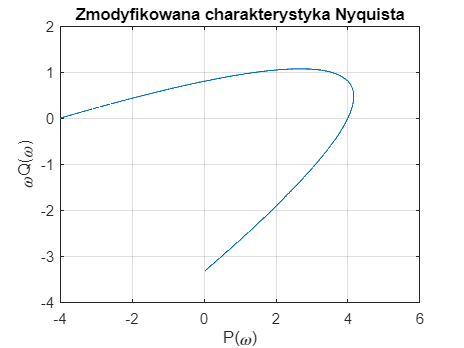


figure
plot(P(:, :), w.*Q(:, :)');
grid on;
title('Zmodyfikowana charakterystyka Nyquista');
xlabel('P(\omega)');
ylabel('\omegaQ(\omega)');

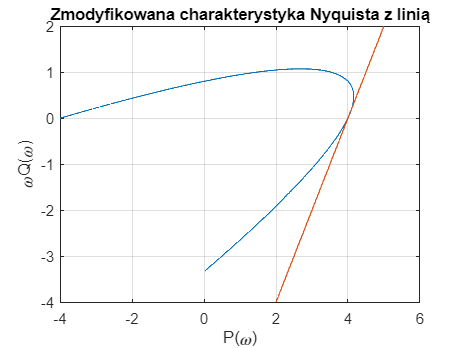


figure
plot(P(:, :), w.*Q(:, :)');
grid on;
title('Zmodyfikowana charakterystyka Nyquista z linią');
xlabel('P(\omega)');
ylabel('\omegaQ(\omega)');
hold on;
plot(x, a*x+b)


m = 1/(-b/a)

m = 0.2500

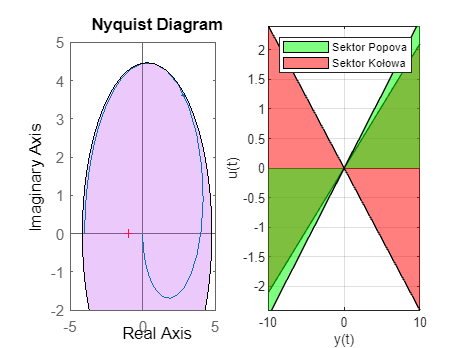

m1m2plot(m1, m2, G_L, m)

# Regulator

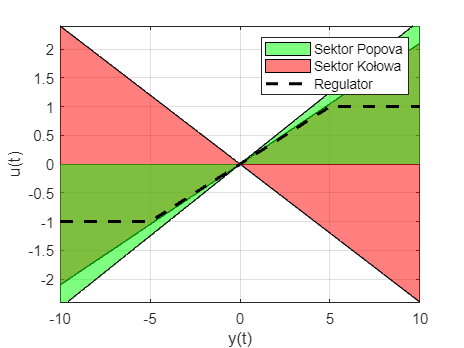

figure
%x is Y here
x = -10:0.1:10;
%y are U here
y1 = m1*x;
y2 = m2*x;

plot(x, y1, x, y2);
xlim([min(x), max(x)]);
ylim([min([y1, y2]), max([y1, y2])]);
hold on;
%Sektor kołowa
a_k = area(x,y1, 'FaceColor', 'r', 'FaceAlpha', 0.5);
area(x,y2, 'FaceColor', 'r', 'FaceAlpha', 0.5);
grid on;
hold on;
%Sektor
a_p = area(x, m*x, 'FaceColor', 'g', 'FaceAlpha', 0.5);
%Regulator
p_r = plot(x, regulator(x), "LineWidth", 2, "LineStyle","--", "Color", [0 0 0]);
legend([a_p, a_k, p_r], ["Sektor Popova", "Sektor Kołowa", "Regulator"])
xlabel("y(t)")
ylabel("u(t)")

function [u] = regulator(y)
    k = 0.2;
    umin = -1;
    umax = 1;

    %u = atan(y)*k;
    u = k * y;

    u(u > umax) = umax;
    u(u < umin) = umin;
end %

function [] = m1m2plot(m1, m2, G, m)
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
    figure;
    subplot(1, 2, 1);
    nyquistplot(G, plotoptions)

    hold on
    if(1/m1 ==0 || 1/m2 ==0 )
        if (1/m1 == 0 && 1/m2 > 0)
            fill ([-100, -100, 1/m2, 1/m2] ,[-100, +100, +100, -100] ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end
        if (1/m1 < 0 && 1/m2 == 0)
            fill ([1/m1, 1/m1, 100, 100] ,[-100, +100, +100, -100] ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end
    else
        theta = linspace(0, 2*pi, 100);
        y0 = 0;
        x0 = (1/m1 + 1/m2) / 2;
        v = abs(1/m1 - 1/m2) / 2;
        x = x0 + v*cos(theta);
        y = y0 + v*sin(theta);

        if(1/m1 * 1/m2 > 0)
            disp("OUTSIDE THE CIRCLE")
            fill (x ,y ,[0.3010  0.9330 0.7450],'FaceAlpha',0.3);
        else
            fill (x ,y ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end

    end
    
    subplot(1, 2, 2);
    x = [-10, 10];
    y1 = m1*x;
    y2 = m2*x;

    plot(x, y1, x, y2);
    xlim(x);
    ylim([min([y1, y2]), max([y1, y2])]);
    hold on;
    a_k = area(x,y1, 'FaceColor', 'r', 'FaceAlpha', 0.5);
    area(x,y2, 'FaceColor', 'r', 'FaceAlpha', 0.5);
    grid on;
    hold on;
    a_p = area(x, m*x, 'FaceColor', 'g', 'FaceAlpha', 0.5);
    legend([a_p, a_k], ["Sektor Popova", "Sektor Kołowa"])
    xlabel("y(t)")
    ylabel("u(t)")
end